taus = [];
Ks = [];

Calibration 1

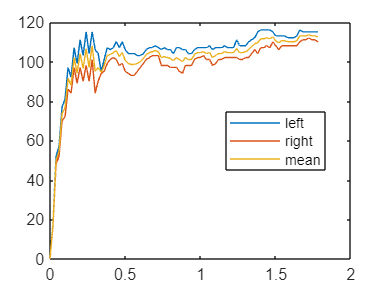


data = readtable('output_motor_cal1.txt');

L_vel = data.Var1;
R_vel = data.Var2;
R_vel = erase(R_vel,';');
R_vel = cellfun(@str2num,R_vel);
t = 0:0.02:10;

L_vel = L_vel(1:90);
R_vel = R_vel(1:90);
L_vel = L_vel*10;
R_vel = R_vel*10;
speedLeft / ((float)162.5) / 12.0 * 80.0 / 10.0 * 3.14159;
t = t(1:length(L_vel))';
V_mean = (L_vel + R_vel)/2;


figure()
plot(t, L_vel)
hold on
plot(t, R_vel)
plot(t, V_mean)
legend('left', 'right', 'mean', 'location', 'best')


V_time_domain = @(K, tau, t) Vdrive*K*(1-exp(-t/tau));

meanFit = createStepResponseFit(t, V_mean)

'createStepResponseFit' is not found in the current folder or on the MATLAB path, but exists in:
    C:\Users\eabbot\Documents\GitHub\rocky-project\MATLAB Processing

Change the MATLAB current folder or add its folder to the MATLAB path.

taus = [taus; meanFit.tau];
Ks = [Ks; meanFit.K];

rightFit = createStepResponseFit(t, R_vel)
leftFit = createStepResponseFit(t, L_vel)

Calibration 2

data = readtable('output_motor_cal2.txt');

L_vel = data.Var1;
R_vel = data.Var2;
R_vel = erase(R_vel,';');
R_vel = cellfun(@str2num,R_vel);
t = 0:0.02:10;

L_vel = L_vel(1:94);
R_vel = R_vel(1:94);
L_vel = L_vel*10;
R_vel = R_vel*10;
t = t(1:length(L_vel))';
V_mean = (L_vel + R_vel)/2;


figure()
plot(t, L_vel)
hold on
plot(t, R_vel)
plot(t, V_mean)
legend('left', 'right', 'mean', 'location', 'best')


V_time_domain = @(K, tau, t) Vdrive*K*(1-exp(-t/tau));

meanFit = createStepResponseFit(t, V_mean)
taus = [taus; meanFit.tau];
Ks = [Ks; meanFit.K];
rightFit = createStepResponseFit(t, R_vel)
leftFit = createStepResponseFit(t, L_vel)

Calibration 3

data = readtable('output_motor_cal3.txt');

L_vel = data.Var1
R_vel = data.Var2;
R_vel = erase(R_vel,';');
R_vel = cellfun(@str2num,R_vel);
L_vel = L_vel(1:94);
R_vel = R_vel(1:94);
L_vel = L_vel*10;
R_vel = R_vel*10;
t = 0:0.02:10;
t = t(1:length(L_vel))';
V_mean = (L_vel + R_vel)/2;


figure()
plot(t, L_vel)
hold on
plot(t, R_vel)
plot(t, V_mean)
legend('left', 'right', 'mean', 'location', 'best')

V_time_domain = @(K, tau, t) Vdrive*K*(1-exp(-t/tau));

meanFit = createStepResponseFit(t, V_mean)
taus = [taus; meanFit.tau];
Ks = [Ks; meanFit.K];

rightFit = createStepResponseFit(t, R_vel)
leftFit = createStepResponseFit(t, L_vel)

Ks
K = mean(Ks)
taus
tau = mean(taus)

save('New-Rocky-MotorResponse3-2-23', 'tau', 'K', 'taus', 'Ks')
